clear all


t = (0:0.01:0.999)';
colr = get(gca,'colororder');
fig=figure;

fig =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 35
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


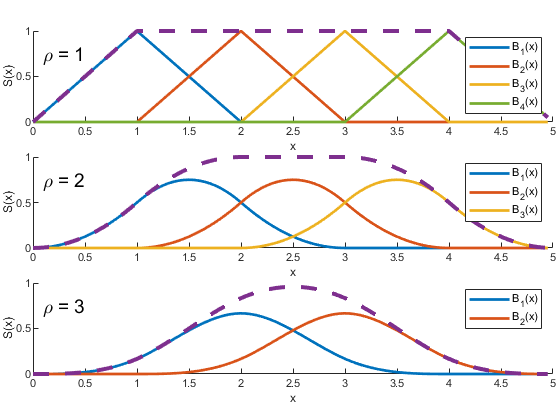


n=1;
m=5;
[un] = basisvectors(t,n,m);

subplot(3,1,1)
hold on
plot(t*5,un{1}(:,2:4),'LineWidth',2)
plot(t*5,un{1}(:,5:5),'LineWidth',2,"Color",colr(5,:))
plot(t*5,sum(un{1}(:,2:5),2),'--','LineWidth',3,'HandleVisibility','off',"Color",colr(4,:))
hold off
xlabel('x')
ylabel('S(x)')
legend('B_{1}(x)','B_{2}(x)','B_{3}(x)','B_{4}(x)','FontSize',8)
colr = get(gca,'colororder');
txt = '\rho = 1';
text(0.1,0.75,txt,'FontSize',14)

ax = gca;
outerpos = ax.OuterPosition;
ti = ax.TightInset; 
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom ax_width ax_height];

n=2;
m=5;
[un] = basisvectors(t,n,m);
subplot(3,1,2)
hold on
plot(t*5,un{1}(:,3:5),'LineWidth',2)
plot(t*5,sum(un{1}(:,3:5),2),'--','LineWidth',3)
hold off
xlabel('x')
ylabel('S(x)')
legend('B_{1}(x)','B_{2}(x)','B_{3}(x)','FontSize',8)
txt = '\rho = 2';
text(0.1,0.75,txt,'FontSize',14)


ax = gca;
outerpos = ax.OuterPosition;
ti = ax.TightInset; 
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom ax_width ax_height];

n=3;
m=5;
[un] = basisvectors(t,n,m);
subplot(3,1,3)
hold on
plot(t*5,un{1}(:,4:5),'LineWidth',2)
plot(0,'--','LineWidth',3,'HandleVisibility','off')
plot(t*5,sum(un{1}(:,4:5),2),'--','LineWidth',3)
hold off
xlabel('x')
ylabel('S(x)')
legend('B_{1}(x)','B_{2}(x)','FontSize',8)
txt = '\rho = 3';
text(0.1,0.75,txt,'FontSize',14)

ax = gca;
outerpos = ax.OuterPosition;
ti = ax.TightInset; 
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom ax_width ax_height];

print(fig,'figures/bsplines','-depsc')